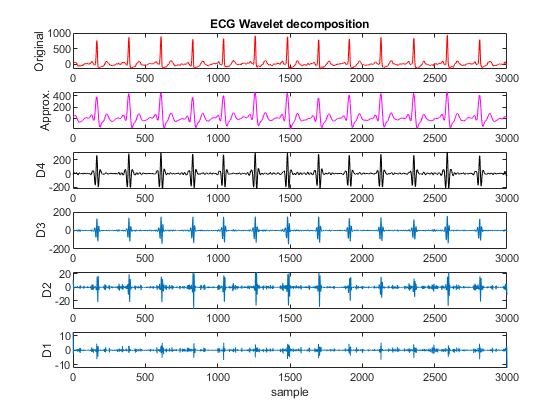

% Decompose Signal using the MODWT
% Generated by MATLAB(R) 9.9 and Wavelet Toolbox 5.5.
% Generated on: 30-Sep-2021 14:34:55
% Logical array for selecting reconstruction elements
levelA = [false, false, false, false, true];
levelD4 = [false, false, false, true, false];
levelD3 = [false, false, true, false, false];
levelD2 = [false, true, false, false, false];
levelD1 = [true, false, false, false, false];
% Perform the decomposition using modwt
wt = modwt(ecg, 'sym4', 4);
% Construct MRA matrix using modwtmra
mra = modwtmra(wt, 'sym4');
% Sum along selected multiresolution signals
ecgA = sum(mra(levelA,:),1);
ecgD4 = sum(mra(levelD4,:),1);
ecgD3 = sum(mra(levelD3,:),1);
ecgD2 = sum(mra(levelD2,:),1);
ecgD1 = sum(mra(levelD1,:),1);
figure(1)
subplot(6,1,1); plot(ecg,'r');ylabel('Original');title('ECG Wavelet decomposition')
subplot(6,1,2); plot(ecgA,'m');ylabel('Approx.')
subplot(6,1,3); plot(ecgD4,'k');ylabel('D4')
subplot(6,1,4); plot(ecgD3);ylabel('D3')
subplot(6,1,5); plot(ecgD2);ylabel('D2')
subplot(6,1,6); plot(ecgD1); xlabel('sample'); ylabel('D1')


    cfs = abs(fb.wt(ecg));

Unable to resolve the name fb.wt.

    im = ind2rgb(im2uint8(rescale(cfs)),jet(300));